LA_Path = "/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code/Datasets/USA/LASEA/LA_AVG_AQ_VALS.csv";
SEA_Path = "/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code/Datasets/USA/LASEA/SEA_AVG_AQ_VALS.csv";

LA_AQ_Table = AQ_table(LA_Path);
SEA_AQ_Table = AQ_table(SEA_Path);

[dates, LA_AQ_Table, SEA_AQ_Table] = same_dates(LA_AQ_Table, SEA_AQ_Table);

writetable(LA_AQ_Table, '/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code/Datasets/USA/LASEA/LA_AQ_Table.csv');
writetable(SEA_AQ_Table, '/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code/Datasets/USA/LASEA/SEA_AQ_Table.csv');

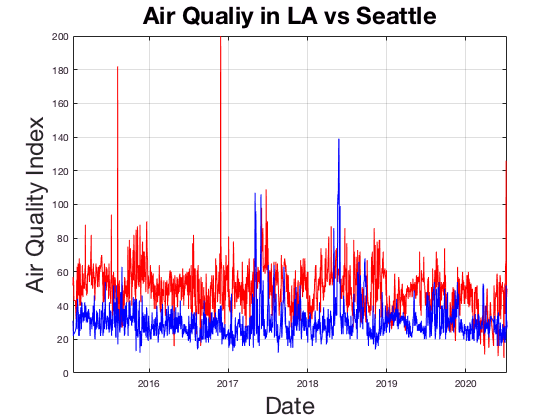

% Plotting AQ in LA vs Seattle 
figure(1)
plot(dates, LA_AQ_Table.AQ, '-r') 
hold on
plot(dates, SEA_AQ_Table.AQ, '-b')
ylim([0 200])
xlabel('Date', 'FontSize', 24)
ylabel('Air Quality Index', 'FontSize', 24)
grid on;
title('Air Qualiy in LA vs Seattle', 'FontSize', 24);

legend('Air Quality in LA', 'Air Quality in Seattle');

Error using legend>process_inputs (line 582)
Invalid argument. Type 'help legend' for more information.

Error in legend>make_legend (line 340)
[autoupdate,orient,location,position,children,listen,strings,propargs] = process_inputs(ha,argin); %#ok

Error in 

hold off;

% Plotting Moving Average AQ in LA vs Seattle 
MA_AQ_LA = movmean(LA_AQ_Table.AQ, 10);
MA_AQ_SEA = movmean(SEA_AQ_Table.AQ, 10);

figure(2)
plot(dates, MA_AQ_LA, '-r') 
hold on;
plot(dates, MA_AQ_SEA, '-b')
grid on; 
title('Moving Average Air Qualiy in LA vs Seattle');
legend('Air Quality in LA', 'Air Quality in Seattle');
hold off; 

% Evaluating the total differences between AQ in both cities
diff = LA_AQ_Table.AQ-SEA_AQ_Table.AQ;
Same_Value_pct = (length(diff(diff==0))/length(diff))*100
LA_Higher_pct = (length(nonzeros(diff(diff>0)))/length(diff))*100
SEA_Higher_pct = (length(nonzeros(diff(diff<0)))/length(diff))*100

LA_Higher = zeros(length(diff), 1);
SEA_Higher = zeros(length(diff), 1);

for i = 1:length(diff)
    if diff(i)>0
        LA_Higher(i) = diff(i);
        SEA_Higher(i) = nan; 
    end 
    if diff(i)<0
        LA_Higher(i) = nan; 
        SEA_Higher(i) = diff(i);
    end 
end 

figure(3)
plot(LA_AQ_Table.date, LA_Higher, '*r')
hold on; 
plot(SEA_AQ_Table.date, SEA_Higher, '*b')
ylim([-150 150]);
xlabel('Date', 'FontSize', 24) 
ylabel('Magnitude of Air Quality Difference', 'FontSize', 24)
grid on;
title('Air Quality Difference between LA and Seattle', 'FontSize', 24);
legend('AQ Higher in LA', 'AQ Higher in Seattle');

function AQ_Table = AQ_table(filename)
    % Read file into a table 
    AQ_Table = readtable(filename);
    % Create an air quality column (Max value of all columns per day)
    AQ_Col = max([AQ_Table.pm25, AQ_Table.o3, AQ_Table.no2, AQ_Table.so2, AQ_Table.co], [], 2);
    AQ_Table.AQ = AQ_Col;
    % Change dates to matlabs datetime object
    AQ_Table.date = datetime(AQ_Table.date,'InputFormat','yyyy/MM/dd');
    % Sort by date 
    [~,idx] = sort(AQ_Table.date, 'descend');
    AQ_Table = AQ_Table(idx,:);
end 

function [dates,Table1_o Table2_o] = same_dates(Table1, Table2) 
    % Setting the length of both tables to that of the shorter table 
    max_len = min(length(Table1.date), length(Table2.date));
    Table1 = Table1(1:max_len, :);
    Table2 = Table2(1:max_len, :);
    
    % Finding all the common dates between both tables 
    [dates, idx1, idx2] = intersect(Table1.date, Table2.date, 'stable');
    
    % Indexing the tables to only include common dates 
    Table1_o = Table1(idx1, :);
    Table2_o = Table2(idx2, :);
end 
